cam = webcam;
preview(cam);
img = snapshot(cam);
imshow(img);

img = imread('circlesBrightDark.png');

img_gray = img;
%img_gray = rgb2gray(img);

%umbral = graythresh(img_gray);
%img_binaria = imbinarize(img_gray, umbral);
%imshow(img_binaria)

%imgbinaria = bwareaopen(img_binaria, 100);
%img_binaria = imfill(img_binaria, 'holes');
%imshow(img_binaria)

img_binaria = img_gray;

stats = regionprops("table", img_binaria, "Centroid", "MajorAxisLength", "MinorAxisLength", "BoundingBox");

[f, c] = size(img_binaria)

f = 512

c = 512

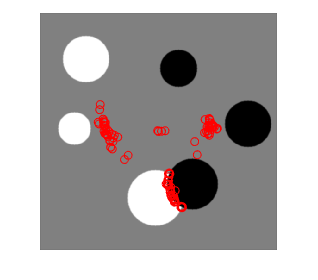


imshow(img_binaria)
hold on
plot(stats.Centroid(:,1), stats.Centroid(:,2), 'or')
hold off